# Thermoeconomic Analysis Demo

Use `ThermoeconomicAnalysis` function to compute the exergy cost of a plant

#### Select and read the data model file

filename="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(1));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.SampleNames);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Perform Cost Analysis

Compute cost and show the results

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);


Process Exergy Cost - REF

Key        P*(kW)     Pe*(kW)     Pr*(kW)      F*(kW)      R*(kW)
——————————————————————————————————————————————————————————————————
BLR       115.982     100.000      15.982     100.000      15.982
TRB       104.894      90.440      14.454     104.894       0.000
IHE         3.370       2.906       0.464       3.370       0.000
PMP         4.894       4.220       0.674       4.894       0.000
CND        15.982      13.780       2.202      15.982       0.000


Process Unit Exergy Cost - REF

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.5642      1.3486      0.2155      1.0000      0.2155      1.3486
TRB        2.0000      1.7244      0.2756      1.5973      0.0000      1.2521
IHE        2.1842      1.8832      0.3010      1.5973      0.0000      1.3675
PMP        2.3383      2.0161      0.3222      2.0000      0.0000      1.1691
CND   

#### Show the default thermoeconomic analysis graph

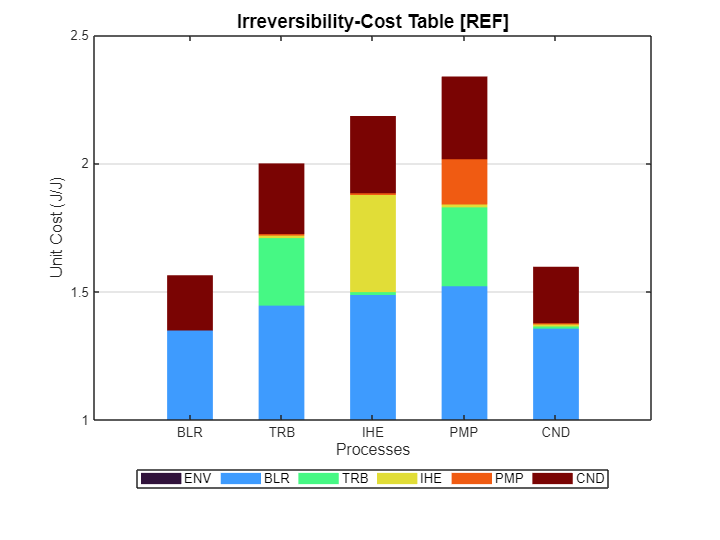

ShowGraph(res);

#### Additional Help

help ThermoeconomicAnalysis

 ThermoeconomicAnalysis gets the termoeconomic analysis of a plant state.
    Calculate the exergy cost, Fuel-Product and Irreversibility-Cost tables.
    If the data model has information on resource costs, generalised costs can be calculated, 
    otherwise only direct costs can be calculated.
    With the option 'CostTables' we choose the type of costs we want to calculate. 
    With the option 'ResourceSample' we choose the resource cost sample data.
 
  Syntax
    res=ThermoeconomicAnalysis(data,Name,Value)
 
  Input Arguments
  	data - cDataModel object which contains the data model
 
  Name-Value Arguments
    State - Thermoeconomic state id. If missing first sample is taken
      array char | string
    CostTables - Indicate which cost tables are calculated
      'DIRECT' calculates direct exergy cost tables
      'GENERALIZED' calculates generalized exergy cost tables
      'ALL' calculate both kind of tables
    ResourceSample - Select a samp